% clear work space
close all
clear variables

expt_1 = importdata("20190424_1556109198799_40.csv");
expt_2 = importdata("20190424_1556110417527_60.csv");
expt_3 = importdata("20190424_1556111709829_90.csv");
expt_4 = importdata("20190424_1556112994514_140.csv");
expt_5 = importdata("20190424_1556114640031_250.csv");

time_1 = expt_1.data(:, 1);
V_1 = expt_1.data(:, 2);
time_2 = expt_2.data(:, 1);
V_2 = expt_2.data(:, 2);
time_3 = expt_3.data(:, 1);
V_3 = expt_3.data(:, 2);
time_4 = expt_4.data(:, 1);
V_4 = expt_4.data(:, 2);
time_5 = expt_5.data(:, 1);
V_5 = expt_5.data(:, 2);

% коэффициенты полинома
p_1 = polyfit(time_1, V_1, 4);
p_2 = polyfit(time_2, V_2, 4);
p_3 = polyfit(time_3, V_3, 4);
p_4 = polyfit(time_4, V_4, 4);
p_5 = polyfit(time_5, V_5, 3);

% сгенерируем точки, равномерно расположенные на области определения данных
x_1 = linspace(time_1(1), time_1(end), 100);
x_2 = linspace(time_2(1), time_2(end), 100);
x_3 = linspace(time_3(1), time_3(end), 100);
x_4 = linspace(time_4(1), time_4(end), 100);
x_5 = linspace(time_5(1), time_5(end), 100);

% получим значения полиномов в этих точках
y_1 = polyval(p_1, x_1);
y_2 = polyval(p_2, x_2);
y_3 = polyval(p_3, x_3);
y_4 = polyval(p_4, x_4);
y_5 = polyval(p_5, x_5);

fig_1 = figure

fig_1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


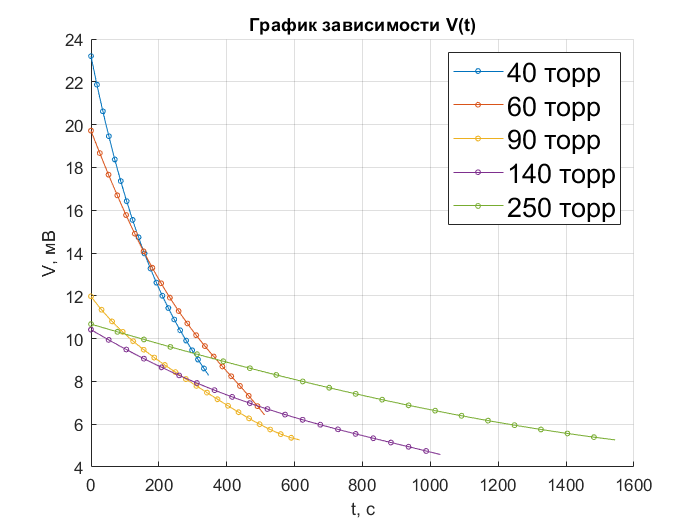


hold on

plot(x_1, y_1, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_1));
plot(x_2, y_2, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_2));
plot(x_3, y_3, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_3));
plot(x_4, y_4, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_4));
plot(x_5, y_5, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_5));

xlabel('t, с');
ylabel('V, мВ');
title('График зависимости V(t)');
lnd = legend('40 торр', '60 торр', '90 торр', '140 торр', '250 торр', 'Location', 'northeast');
lnd.FontSize = 16;
grid on
hold off

set(fig_1, 'Visible', 'on')

% логорифм показаний вольтметра
lnV_1 = log(V_1);
lnV_2 = log(V_2);
lnV_3 = log(V_3);
lnV_4 = log(V_4);
lnV_5 = log(V_5);

lin_1 = polyfit(time_1, lnV_1, 1);
lin_2 = polyfit(time_2, lnV_2, 1);
lin_3 = polyfit(time_3, lnV_3, 1);
lin_4 = polyfit(time_4, lnV_4, 1);
lin_5 = polyfit(time_5, lnV_5, 1);

yy_1 = polyval(lin_1, x_1);
yy_2 = polyval(lin_2, x_2);
yy_3 = polyval(lin_3, x_3);
yy_4 = polyval(lin_4, x_4);
yy_5 = polyval(lin_5, x_5);

fig_2 = figure

fig_2 =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


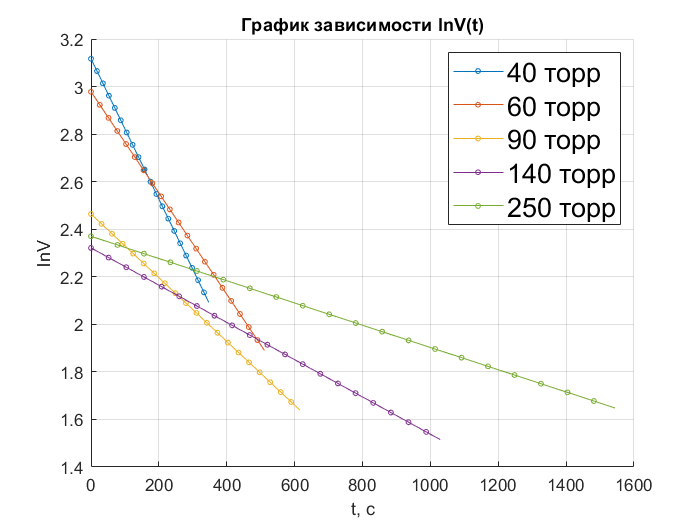


hold on

plot(x_1, yy_1, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_1));
plot(x_2, yy_2, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_2));
plot(x_3, yy_3, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_3));
plot(x_4, yy_4, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_4));
plot(x_5, yy_5, '-o', 'MarkerSize', 3, 'MarkerIndices', 1:5:length(y_5));

xlabel('t, с');
ylabel('lnV');
title('График зависимости lnV(t)');
lnd = legend('40 торр', '60 торр', '90 торр', '140 торр', '250 торр', 'Location', 'northeast');
lnd.FontSize = 16;
grid on
hold off

set(fig_2, 'Visible', 'on')

%saveas(fig_1, "V(t).png");
%saveas(fig_2, "lnV(t).png");